%测试模型数据迁移的效果
clear all
addpath('code');
addpath('tests');
load('Nor_Data128_GreenHouse_Cate_ReOederTime_OJIPZscore.mat');
%注Data_PEA是OJIPSNV后的数据，Data_PEA_128是原始数据。

MaxFP=max(Data_FP);
MinFP=min(Data_FP);
MaxPEA=max(Data_PEA);
MinPEA=min(Data_PEA);

Data_FP_input=normalize(Data_FP,'range',[-1,1]);%Minmax归一化 各个参数
Data_PEA_input=normalize(Data_PEA,'range',[-1,1]);

MaxFP_128=max(Data_FP_128);
MinFP_128=min(Data_FP_128);
MaxPEA_128=max(Data_PEA_128);
MinPEA_128=min(Data_PEA_128);

Data_FP_input_Orin=normalize(Data_FP_128,'range',[-1,1]);%Minmax归一化 各个参数
Data_PEA_input_Orin=normalize(Data_PEA_128,'range',[-1,1]);

%SNV处理
Data_FP_input_SNV=normalize(Data_FP,'range',[-1,1]);
Data_PEA_input_SNV=normalize(Data_PEA,'range',[-1,1]);
Data_FP_input_SNV=normalize(Data_FP_input_SNV,'range',[-1,1]);%Minmax归一化 各个参数
Data_PEA_input_SNV=normalize(Data_PEA_input_SNV,'range',[-1,1]);

%随机生成一个范围内的数
random_integer = randi([0, floor(2985*0.7)]);

%%展示FtF的原始迁移效果
load('Result_PtP_E225_Orin_FP_PEA.mat','p2pModel');

exampleInput(:,1)=Data_FP_input_Orin(random_integer,:);
exampleOutput = tanh(p2p.translate(p2pModel, exampleInput));
exampleOutput_FtF_Orin=double(extractdata(gather(exampleOutput(:,1,1))))';
exampleOutput_FtF_Orin_P1=inverse_MinMax(exampleOutput_FtF_Orin,MaxPEA_128,MinPEA_128);

exampleOutput_FtF_Orin_P2=OJIPSNV_PEA(exampleOutput_FtF_Orin_P1,...
    Data_PEA_F0_AVE, Data_PEA_F0_STD, Data_PEA_OJ_AVE, Data_PEA_OJ_STD, Data_PEA_JI_AVE,...
    Data_PEA_JI_STD, Data_PEA_IP_AVE, Data_PEA_IP_STD,Data_PEA_STD,Data_PEA_AVE);
exampleOutput_FtF_Orin_P2=(exampleOutput_FtF_Orin_P2-MinPEA).*2./(MaxPEA-MinPEA)-1;


% %%展示FtF的原始迁移效果
% load('Result_PtP_E300_SNV_FP_PEA.mat','p2pModel');
% 
% exampleInput(:,1)=Data_FP_input_Orin(random_integer,:);
% exampleOutput = tanh(p2p.translate(p2pModel, exampleInput));
% exampleOutput_FtF_Orin=double(extractdata(gather(exampleOutput(:,1,1))))';
% exampleOutput_FtF_Orin_P1=inverse_MinMax(exampleOutput_FtF_Orin,MaxPEA_128,MinPEA_128);
% 
% exampleOutput_FtF_Orin_P2=OJIPSNV_PEA(exampleOutput_FtF_Orin_P1,...
%     Data_PEA_F0_AVE, Data_PEA_F0_STD, Data_PEA_OJ_AVE, Data_PEA_OJ_STD, Data_PEA_JI_AVE,...
%     Data_PEA_JI_STD, Data_PEA_IP_AVE, Data_PEA_IP_STD,Data_PEA_STD,Data_PEA_AVE);
% exampleOutput_FtF_Orin_P2=(exampleOutput_FtF_Orin_P2-MinPEA).*2./(MaxPEA-MinPEA)-1;

%
load('Result_FtF_E500_OJIPSNV_FP_PEA.mat','p2pModel');

exampleInput(:,1)=Data_FP_input(random_integer,:);
exampleOutput = tanh(p2p.translate(p2pModel, exampleInput));

exampleOutput_FtF_OJIPSNV_P2=double(extractdata(gather(exampleOutput(:,1,1))))';
exampleOutput_FtF_OJIPSNV_P1=inverse_PEA_processing(inverse_MinMax(exampleOutput_FtF_OJIPSNV_P2,MaxPEA,MinPEA),...
    Data_PEA_F0_AVE, Data_PEA_F0_STD, Data_PEA_OJ_AVE, Data_PEA_OJ_STD, Data_PEA_JI_AVE,...
    Data_PEA_JI_STD, Data_PEA_IP_AVE, Data_PEA_IP_STD,Data_PEA_STD,Data_PEA_AVE);


load('Result_PtP_E500_OJIPSNV_FP_PEA.mat','p2pModel');

exampleInput(:,1)=Data_FP_input(random_integer,:);
exampleOutput = tanh(p2p.translate(p2pModel, exampleInput));
exampleOutput_PtP_OJIPSNV_P2=double(extractdata(gather(exampleOutput(:,1,1))))';
exampleOutput_PtP_OJIPSNV_P1=inverse_PEA_processing(inverse_MinMax(exampleOutput_PtP_OJIPSNV_P2,MaxPEA,MinPEA),...
    Data_PEA_F0_AVE, Data_PEA_F0_STD, Data_PEA_OJ_AVE, Data_PEA_OJ_STD, Data_PEA_JI_AVE,...
    Data_PEA_JI_STD, Data_PEA_IP_AVE, Data_PEA_IP_STD,Data_PEA_STD,Data_PEA_AVE);

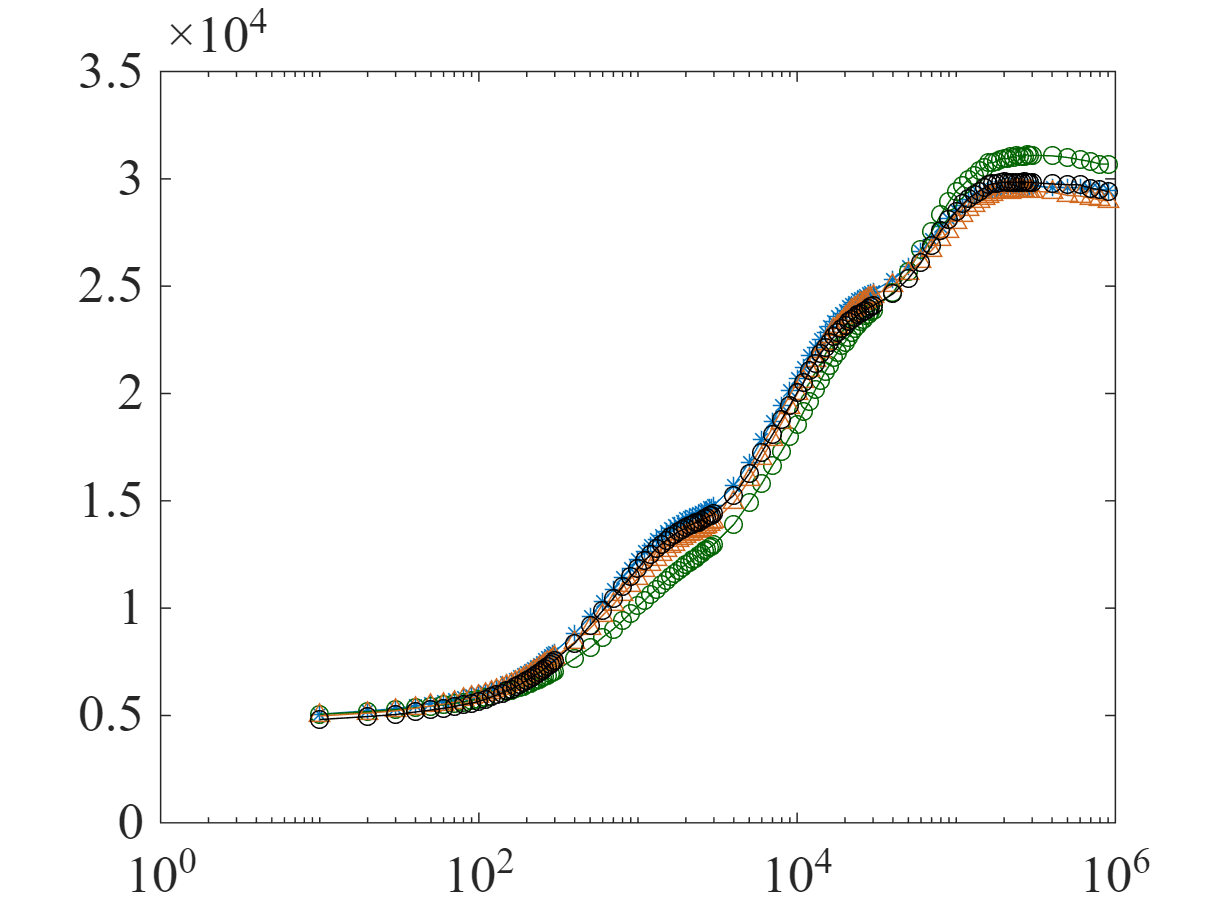


%P1
figure
xlabel('Time(ns)');
ylabel('Fluorescence inestensity');

% 显示网格（可选）
grid on;
semilogx(Time_128(1:end-10),Data_PEA_Orin_Para(random_integer,1:end-10),'-*');
hold on;
semilogx(Time_128(1:end-10),exampleOutput_FtF_Orin_P1(1:end-10),'-o','color','#006400');
semilogx(Time_128(1:end-10),exampleOutput_FtF_OJIPSNV_P1(1:end-10),'-^','color','#D2691E');
semilogx(Time_128(1:end-10),exampleOutput_PtP_OJIPSNV_P1(1:end-10),'-o','Color','k');
%legend('Target Fluorescence Data','1D-Pix2Pix(OJIPSNV)','FluoToFluo(OJIPSNV)');
%legend('Target Fluorescence Data','FluoToFluo(SNV)','1D-Pix2Pix(OJIP-SNV)','FluoToFluo(OJIP-SNV)');
ax = gca;
ax.FontSize = 18;
ax.FontName = 'Times New Roman';


% 设置 x 轴标签的字体
ax.XLabel.FontSize = 18;
ax.XLabel.FontName = 'Times New Roman';


% 设置 y 轴标签的字体
ax.YLabel.FontSize = 18;
ax.YLabel.FontName = 'Times New Roman';


hold off;
grid off;

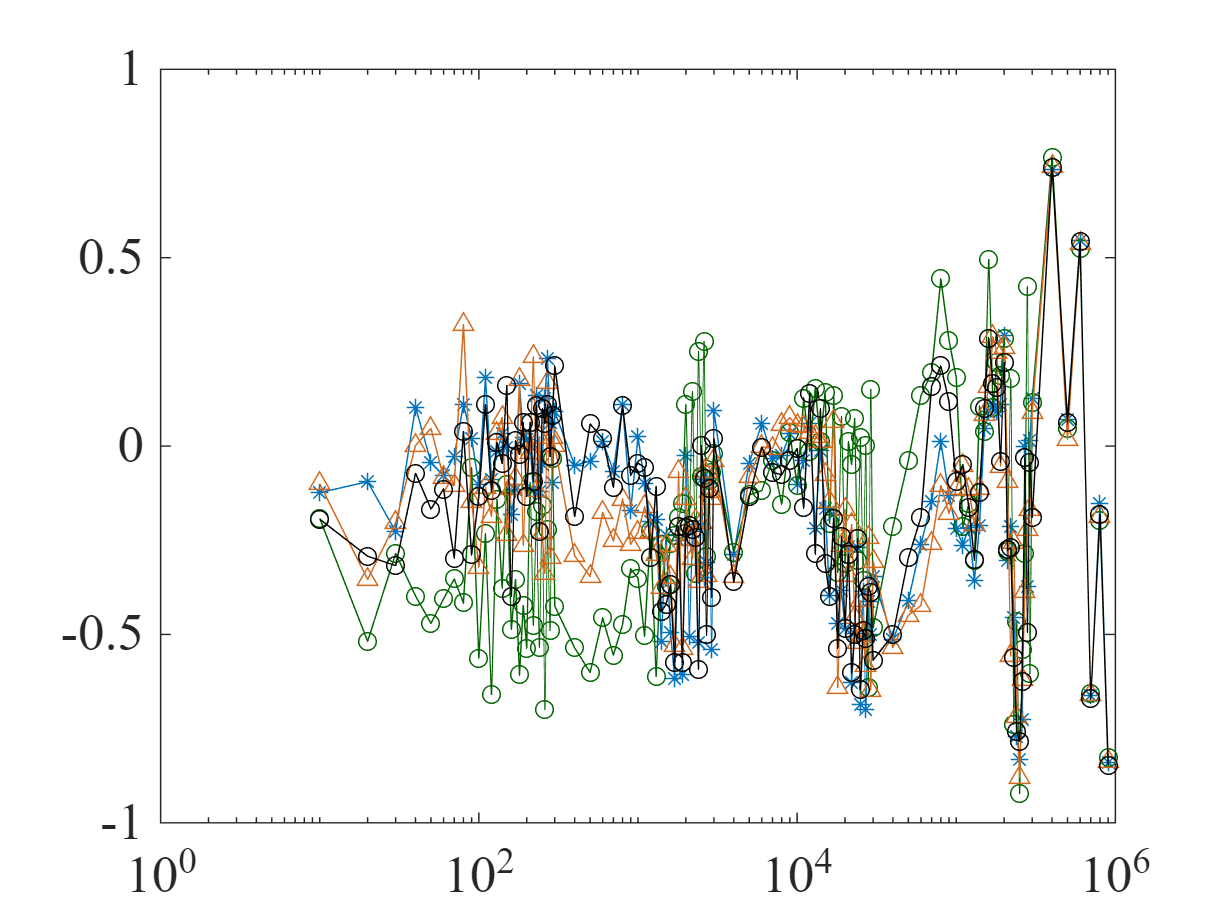


figure
xlabel('Time(ns)');
ylabel('Fluorescence value');

% 显示网格（可选）
Data_PEA_OJIPSNV=Data_PEA_input(random_integer,:);


grid on;
semilogx(Time_128(2:end-10),Data_PEA_OJIPSNV(2:end-10),'-*');
hold on;
semilogx(Time_128(2:end-10),exampleOutput_FtF_Orin_P2(2:end-10),'-o','color','#006400');
semilogx(Time_128(2:end-10),exampleOutput_FtF_OJIPSNV_P2(2:end-10),'-^','color','#D2691E');
semilogx(Time_128(2:end-10),exampleOutput_PtP_OJIPSNV_P2(2:end-10),'-o','Color','k');
%legend('Target FluorescenceData','1D-Pix2Pix(OJIPSNV)','FluoToFluo(OJIPSNV)');
%legend('Target Fluorescence Data','FluoToFluo(Orin)','1D-Pix2Pix(OJIPSNV)','FluoToFluo(OJIPSNV)');
ax = gca;
ax.FontSize = 18;
ax.FontName = 'Times New Roman';


% 设置 x 轴标签的字体
ax.XLabel.FontSize = 18;
ax.XLabel.FontName = 'Times New Roman';


% 设置 y 轴标签的字体
ax.YLabel.FontSize = 18;
ax.YLabel.FontName = 'Times New Roman';

%MinMax反演
function Aimdata=inverse_MinMax(data,maxnum,minnum)
data=(data+1)/2;
Aimdata=data.*(maxnum-minnum)+minnum;
end

%OJIPSNV反演
function Data_PEA_Orin_Para = inverse_PEA_processing(Data_PEA, F0_AVE,...
    F0_STD, OJ_AVE, OJ_STD, JI_AVE, JI_STD, IP_AVE, IP_STD,Data_STD,Data_AVE)
% 获取数据维度
[num_rows, num_cols] = size(Data_PEA);

Data_PEA=Data_PEA.*Data_STD+Data_AVE;

% 初始化反归一化矩阵
Data_PEA_denorm = zeros(num_rows, num_cols);

% 反归一化F0部分（第一列）
Data_PEA_denorm(:, 1) = Data_PEA(:, 1) * F0_STD + F0_AVE;

% 反归一化OJ部分（2-47列）
if num_cols >= 47
    Data_PEA_denorm(:, 2:47) = Data_PEA(:, 2:47) * OJ_STD + OJ_AVE;
else
    error('数据列数不足，无法处理OJ部分');
end

% 反归一化JI部分（48-86列）
if num_cols >= 86
    Data_PEA_denorm(:, 48:86) = Data_PEA(:, 48:86) * JI_STD + JI_AVE;
else
    error('数据列数不足，无法处理JI部分');
end

% 反归一化IP部分（87列至末尾）
if num_cols >= 87
    Data_PEA_denorm(:, 87:end) = Data_PEA(:, 87:end) * IP_STD + IP_AVE;
else
    error('数据列数不足，无法处理IP部分');
end

% 逆向差分运算重建原始数据
Data_PEA_Orin_Para = zeros(num_rows, num_cols);
Data_PEA_Orin_Para(:, 1) = Data_PEA_denorm(:, 1); % 第一列直接复制

for i = 2:num_cols
    Data_PEA_Orin_Para(:, i) = Data_PEA_denorm(:, i) + Data_PEA_Orin_Para(:, i-1);
end

end



function data=OJIPSNV_PEA(PEAdata,F0_AVE, F0_STD, OJ_AVE, OJ_STD,...
    JI_AVE, JI_STD, IP_AVE, IP_STD,Data_STD,Data_AVE)
Data_PEA_Orin_Para=PEAdata;
for i=1:length(Data_PEA_Orin_Para(1,:))
    if i==1
        data(:,i)=Data_PEA_Orin_Para(:,1);
    else
        data(:,i)=Data_PEA_Orin_Para(:,i)-Data_PEA_Orin_Para(:,i-1);
    end
end

%归一化
data(:,1)=(data(:,1)-F0_AVE)./F0_STD;
data(:,2:47)=(data(:,2:47)-OJ_AVE)./OJ_STD;
data(:,48:86)=(data(:,48:86)-JI_AVE)./JI_STD;
data(:,87:end)=(data(:,87:end)-IP_AVE)./IP_STD;
data=(data-Data_AVE)./Data_STD;
end